% if isequal(exist('tvpvar_test.xlsx', 'file'), 2)
%   delete('tvpvar_test.xlsx');
% end
asvar = {'GDP', 'CO2'};  % 变量名'Population',

使用AIC来确定nlag ----- 问题：论文里面的VAR模型说的是4，1，2，且没有给出code说如何得到这三个nlag的。另外TVP-VAR code里面，nlag全变成了4。所以我尝试先复现nlag=4,1,2。

美国：nlag=4

英国：nlag=4

日本：nlag=4

中国：nlag=4

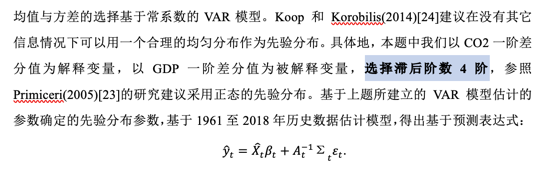

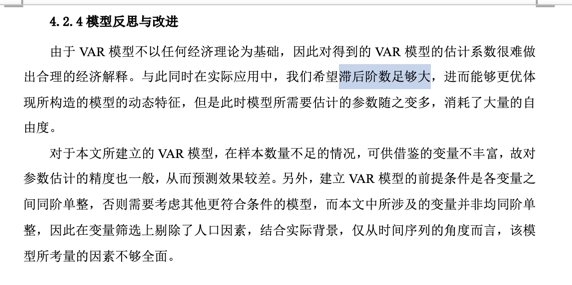

阶数，应该就是lags滞后阶数，这个也是与数据有关，选择方法有几种。我知道的是按AIC和BIC标准选。

可以用MATLAB里自带的函数aicbic算出各阶数的AIC、BIC值，其中最小的那个阶数就是这个方法得出的最有阶数。

**美国AIC -> Mdl里面的y应该是yd_US，但用这个做出来是3；用US_CO2做出来nlag = 4**

**此时var: yd_t = f (yd_t-1) + epsilon**

Mdl(1)=varm(1,1); %这里的第二项就是nlags。第一项是1，因为暂时只考虑us本身，不考虑国家间相互作用
Mdl(2)=varm(1,2);
Mdl(3)=varm(1,3);
Mdl(4)=varm(1,4);


numMdl = numel(Mdl);
logL = zeros(numMdl,1);      % Preallocate
numParam = zeros(numMdl,1);
numObs = zeros(numMdl,1);

y=diff(US_CO2);
% y=US_CO2;
for j = 1:numMdl
    y0 = y(1:Mdl(j).P);             % Presample
    yest = y((Mdl(j).P+1):end);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic = aicbic(logL,numParam,numObs,Normalize=true)

aic =    13.1223
   13.1212
   13.0520
   13.0734


[~,minIdx] = min(aic);
Mdl(minIdx).Description

ans = "1-Dimensional VAR(3) Model"

**英国AIC**

y=diff(UK_CO2);
% y=UK_CO2;
for j = 1:numMdl
    y0 = y(1:Mdl(j).P);             % Presample
    yest = y((Mdl(j).P+1):end);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic = aicbic(logL,numParam,numObs,Normalize=true)

aic =    10.0283
   10.0357
   10.0513
   10.0390


[~,minIdx] = min(aic);
Mdl(minIdx).Description

ans = "1-Dimensional VAR(1) Model"

**日本aic**

y=diff(JAPAN_CO2);
% y=JAPAN_CO2;
for j = 1:numMdl
    y0 = y(1:Mdl(j).P);             % Presample
    yest = y((Mdl(j).P+1):end);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic = aicbic(logL,numParam,numObs,Normalize=true)

aic =     9.7535
    9.7641
    9.7854
    9.8018


[~,minIdx] = min(aic);
Mdl(minIdx).Description

ans = "1-Dimensional VAR(1) Model"

**中国AIC**

y=diff(CHINA_CO2);
% y=CHINA_CO2;
for j = 1:numMdl
    y0 = y(1:Mdl(j).P);             % Presample
    yest = y((Mdl(j).P+1):end);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic = aicbic(logL,numParam,numObs,Normalize=true)

aic =    12.2579
   12.2560
   12.2683
   12.2899


[~,minIdx] = min(aic);
Mdl(minIdx).Description

ans = "1-Dimensional VAR(2) Model"

TVP-VAR是用GDP来估计CO2，而不是用CO2估计自己本身。Anyways，只要能说一个道理为什么选择nlags=4，就都可以解释了。

考虑**四个**国家相互作用：

Mdl(1)=varm(4,1); %这里的第二项就是nlags。第一项是1，因为暂时只考虑us本身，不考虑国家间相互作用
Mdl(2)=varm(4,2);
Mdl(3)=varm(4,3);
Mdl(4)=varm(4,4);


numMdl = numel(Mdl);
logL = zeros(numMdl,1);      % Preallocate
numParam = zeros(numMdl,1);
numObs = zeros(numMdl,1);

y=[diff(US_CO2),diff(UK_CO2),diff(JAPAN_CO2),diff(CHINA_CO2)];
% y=US_CO2;
for j = 1:numMdl
    y0 = y(1:Mdl(j).P,:);             % Presample
    yest = y((Mdl(j).P+1):end,:);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic=aicbic(logL,numParam,numObs,Normalize=true)

aic =    44.9490
   44.9535
   44.9517
   45.0716


考虑三个国家相互作用（论文中）

Mdl(1)=varm(3,1); %这里的第二项就是nlags。第一项是1，因为暂时只考虑us本身，不考虑国家间相互作用
Mdl(2)=varm(3,2);
Mdl(3)=varm(3,3);
Mdl(4)=varm(3,4);


numMdl = numel(Mdl);
logL = zeros(numMdl,1);      % Preallocate
numParam = zeros(numMdl,1);
numObs = zeros(numMdl,1);

y=[diff(US_CO2),diff(UK_CO2),diff(JAPAN_CO2)];
% y=US_CO2;
for j = 1:numMdl
    y0 = y(1:Mdl(j).P,:);             % Presample
    yest = y((Mdl(j).P+1):end,:);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic=aicbic(logL,numParam,numObs,Normalize=true)

aic =    32.6312
   32.6702
   32.6641
   32.6989


因此我给的nlag=4解释是：

综合考虑单国家及多国家VAR模型下的AIC信息量，且一般需要一个比较大的nlag来体现VAR模型的动态特征，我们选择了比当前最优的nlag=3更大一级的nlag=4。

美国预测模拟

xlswrite('tvpvar_test.xlsx', ...
US_data(1:end-2,:), 'Sheet1', 'A1');


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


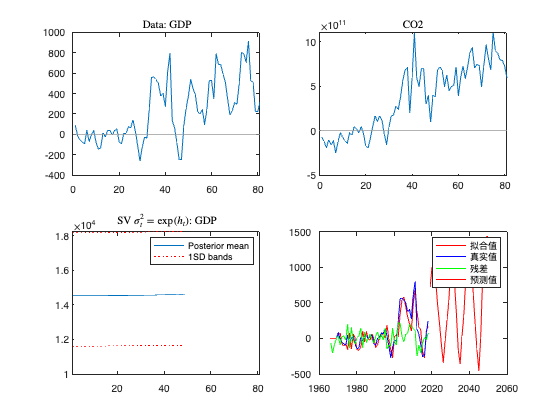

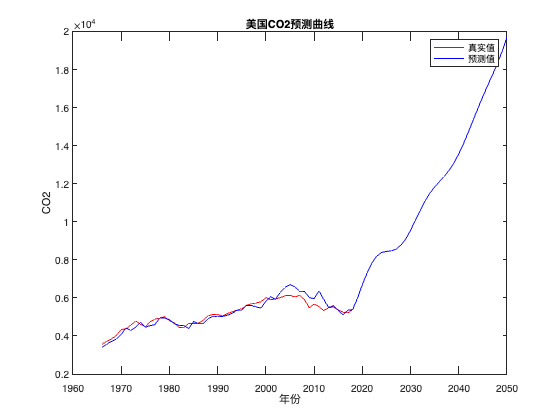

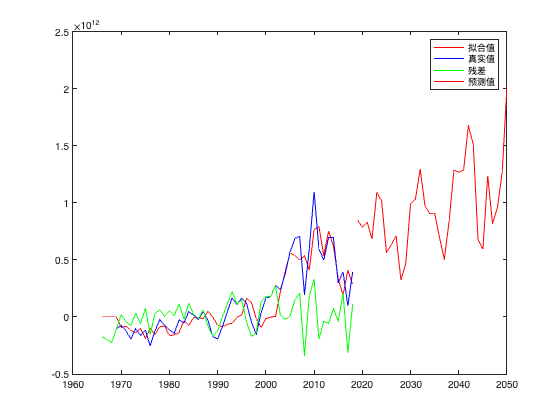

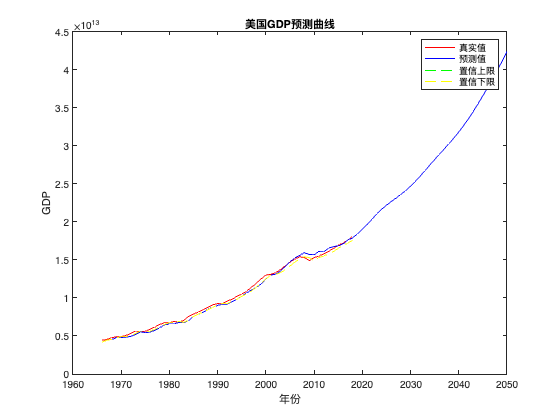



                        [ESTIMATION RESULT]
----------------------------------------------------------------------
Parameter   Mean      Stdev       95%U       95%L    Geweke     Inef.
----------------------------------------------------------------------
sigma_b1       0.0022     0.0000     0.0022     0.0023     0.163      1.06
sigma_b2       0.0022     0.0000     0.0022     0.0023     0.389      0.69
sigma_a1       0.0048     0.0012     0.0031     0.0077     0.027     13.01
sigma_h1       0.0048     0.0012     0.0031     0.0078     0.399     10.06
sigma_h2       0.0048     0.0012     0.0031     0.0080     0.089      9.65
----------------------------------------------------------------------
TVP-VAR model (Lag = 4)
Iteration: 10000
Sigma(b): Diagonal

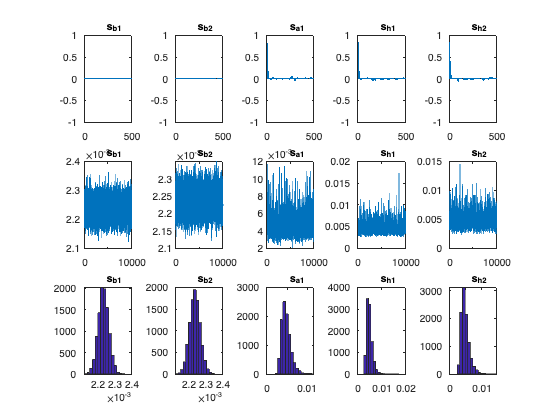

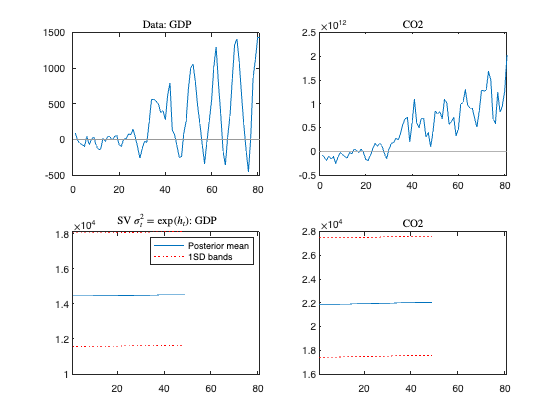

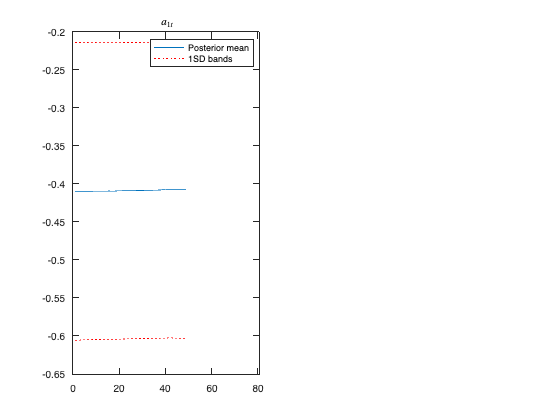

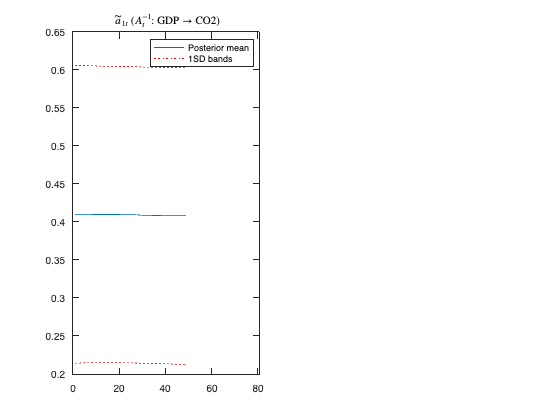



Ranseed: 1
Time: 100.08



% writetable('tvpvar_test.xlsx', ...
%      US_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
% my = readtable('tvpvar_test.xlsx');
nlag = 4;  %    
set_global_variables('data', my, asvar, nlag);  % 设置数据；设置全局的输出变量
set_global_variables('fastimp', 1);  % fast computing of response
[USCO2, USGDP] = mote_carlo_simulation(10000, US_CO2,US_GDP, 0);  %蒙特卡洛模拟10000

碳中和路径

xlswrite('tvpvar_test.xlsx', ...
    US_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[USCO2, USGDP] = carbon_neutrality_path(10000, US_CO2,US_GDP, 0);  %碳中和路径(已设置UStarget）

英国预测模拟

figure()
xlswrite('tvpvar_test.xlsx', UK_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[UKCO2, UKGDP] = mote_carlo_simulation(10000, UK_CO2, UK_GDP, 1);  %蒙特卡洛模拟10000

碳中和路径

figure()
xlswrite('tvpvar_test.xlsx', UK_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[UKCO2, UKGDP] = carbon_neutrality_path(10000, UK_CO2, UK_GDP, 1);  %碳中和路径(已设置UKtarget）

日本预测模拟

figure()
xlswrite('tvpvar_test.xlsx', JAPAN_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[JAPANCO2, JAPANGDP] = mote_carlo_simulation(10000, JAPAN_CO2, JAPAN_GDP, 2);  %蒙特卡洛模拟10000

碳中和路径

figure()
xlswrite('tvpvar_test.xlsx', JAPAN_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[JAPANCO2, JAPANGDP] = carbon_neutrality_path(10000, JAPAN_CO2, JAPAN_GDP, 2);  %碳中和路径(已设置JAPANtarget）

中国预测模拟

figure()
xlswrite('tvpvar_test.xlsx', CHINA_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[CHINACO2, CHINAGDP] = mote_carlo_simulation(10000, CHINA_CO2, CHINA_GDP, 3);  %蒙特卡洛模拟10000

碳中和路径

figure()
xlswrite('tvpvar_test.xlsx', CHINA_data(1:end-2,:), 'Sheet1', 'A1');
my = xlsread('tvpvar_test.xlsx');
nlag = 4;  % 滞后阶数
set_global_variables('data', my, asvar, nlag);  % 设置数据
set_global_variables('fastimp', 1);  % fast computing of response
[CHINACO2, CHINAGDP] = carbon_neutrality_path(10000, CHINA_CO2, CHINA_GDP, 3);  %碳中和路径(已设置Chinatarget）

脉冲响应

figure()
D2_1(1, 1);  % draw D2_8 reponse(1)
                         % : 4-,8-,12-period ahead
%D2_1(1, 0);  % draw D2_8 response(2)
                           % : response at t=30,60,90
